Q-3

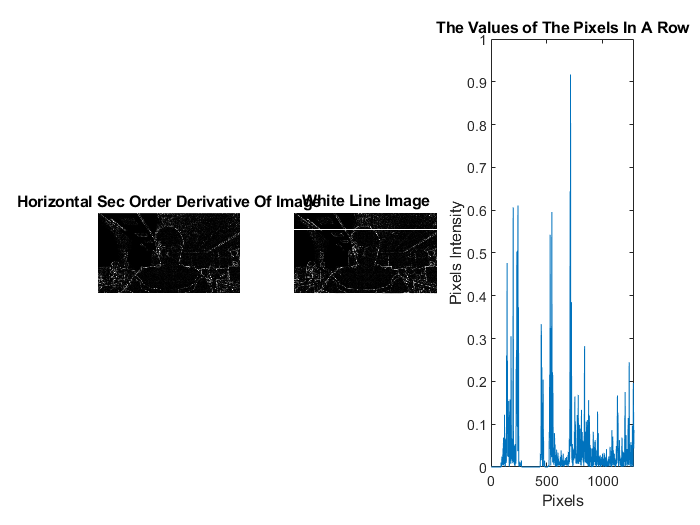

ahmet=imread('ahmet.jpg');
ahmet=im2double(ahmet);
ahmet_gray=rgb2gray(ahmet);
 
 
filter=[-1 -1 -1;-1 8 -1; -1 -1 -1];
image_second_derivative=imfilter(ahmet_gray,filter);
image_second_derivative=abs(image_second_derivative);
row_derivative=image_second_derivative(150,:);
derivative_whiteline=image_second_derivative;
derivative_whiteline(150,:)=1; 
[a,b]=size(row_derivative);
a=1:b; 
 
subplot(1,3,1)
imshow(image_second_derivative)
title('Horizontal Sec Order Derivative Of Image','fontsize', [10])

subplot(1,3,2)
imshow(derivative_whiteline)
title('White Line Image','fontsize', [10])

subplot(1,3,3)
plot(2:a(end)-1,row_derivative(2:b-1))
title('The Values of The Pixels In A Row','fontsize', [10])
xlabel('Pixels')
ylabel('Pixels Intensity')